# **Problem E15.9**

**i.**

We will draw 100 samples from a $U\left(0,1\right)$distribution:

X = rand(1, 100);

**ii.**

Squaring each entry in X so that it no longer follows a uniform distribution:

X = X.^2;

**iii.**

We will then implement a competitve layer to fit on the samples that we have generated. Since the notion of normalization is meaningless in one dimension, we will instead use the alternative structure where instead of setting $a=\textrm{compet}\left(\textrm{Wp}\right)$will use $a=\textrm{compet}\left(-||W-p||_F^{2\;} \right)$. We also use the conscience mechanism to prevent dead neurons.

W = rand(5, 1) - 0.5;
b = zeros(5, 1);
alpha = 0.5;
% take 500 passes on the entire dataset
for i=1:500
    for j=1:length(X)
        n = -(W - X(j)).^2 + b;
        a = compet(n);
        i_star = find(a==1);
        % kohonen rule
        W(i_star) = (1 - alpha)*W(i_star) + alpha*X(j);
        % conscience update
        idx = zeros(5, 1);
        idx(i_star) = idx(i_star) + 1;
        idx = logical(idx);
        b(idx) = b(idx) - 0.2;
        b(~idx) = b(~idx)*0.9;
    end
end

In order to see the potential relationship between the final weights and the samples we can plot them on a single axis:

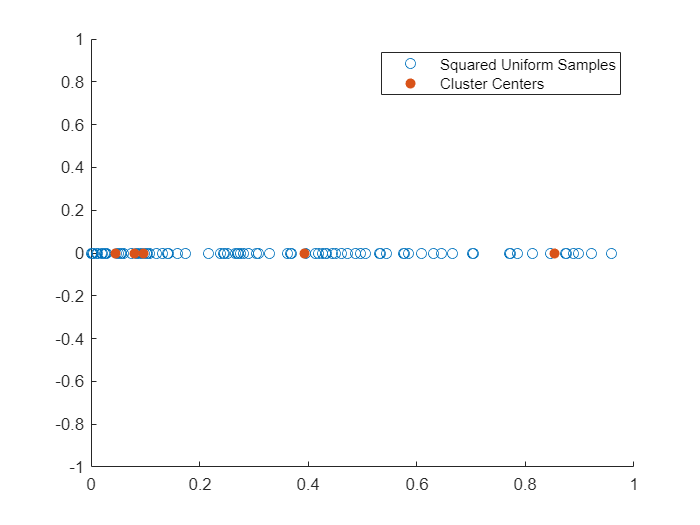

scatter(X, zeros(1, 100));
hold on
scatter(W, zeros(5, 1), 'filled');
legend('Squared Uniform Samples', 'Cluster Centers');
hold off

As we can see we do not have any dead neurons. Moreover, all the weights are distributed roughly in the densest parts of the samples, i.e., towards the lower bound of the numbers. The reason for this is that when the weights are squared, because they all lie in the $\left\lbrack 0,1\right\rbrack$interval, they all become significantly smaller than their previous values, and are essentially squashed down towards 0. 